**Laboratorium 6 – Próbkowanie i rekonstrukcja sygnałów**

**Jakub Szczypek nr 405912**

**grupa 5 WEAIiIB air**

1.1 Ćwiczenie 1

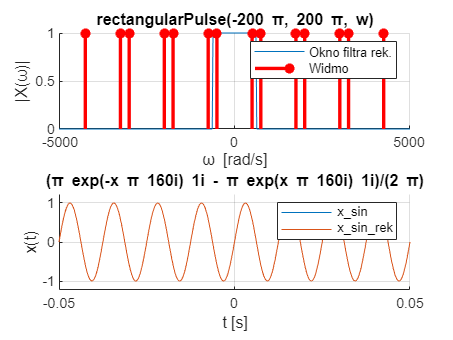

clear all; close all;
syms t x w K


fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;


s = 4/5; ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);


X_FT_sin = X_FT_sin_org + ... % oryginal widma
symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe


FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera


BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];


figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');


subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

1.2 Zadanie 2

Do powyższego przykładu została dodana funkcjonalność, która zaznacza węzły próbkowania na oryginalnym przebiegu czasowym:

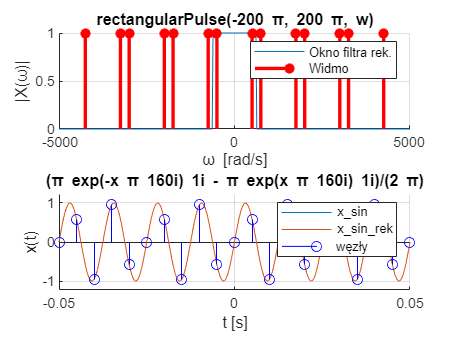

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);
% subplot(2,1,2) ...
stem(wezly, wezly_val, 'b');
legend('x\_sin','x\_sin\_rek', 'węzły');

1.3 Zadanie 3

Podpunkt a) s = 1/5

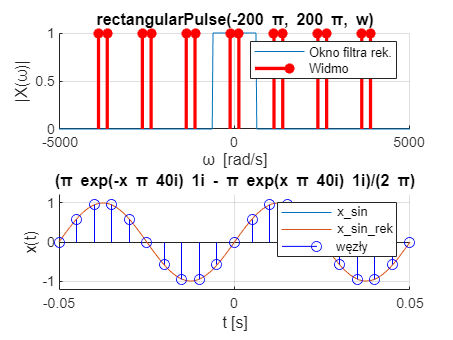

clear all; close all;
syms t x w K


fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;


s = 1/5; ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);


X_FT_sin = X_FT_sin_org + ... % oryginal widma
symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe


FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera


BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];


figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);
subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
stem(wezly, wezly_val, 'b');
legend('x\_sin','x\_sin\_rek', 'węzły');

Podpunkt b) s = 6/5

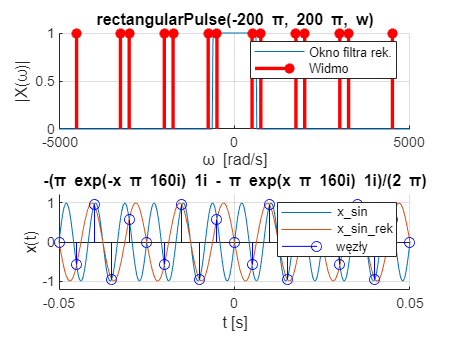

clear all; close all;
syms t x w K


fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;


s = 6/5; ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);


X_FT_sin = X_FT_sin_org + ... % oryginal widma
symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe


FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera


BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];


figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);
subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
stem(wezly, wezly_val, 'b');
legend('x\_sin','x\_sin\_rek', 'węzły');

Podpunkt c) s =11/5

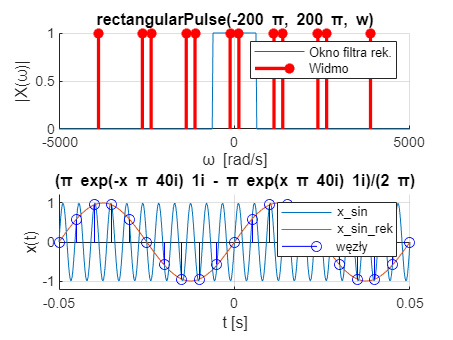

clear all; close all;
syms t x w K


fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;


s = 11/5; ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);


X_FT_sin = X_FT_sin_org + ... % oryginal widma
symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe


FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera


BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];


figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);
subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
stem(wezly, wezly_val, 'b');
legend('x\_sin','x\_sin\_rek', 'węzły');

Podpunkt d) s = 16/5

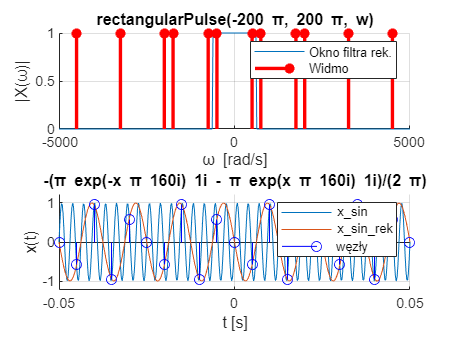

clear all; close all;
syms t x w K


fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;


s = 16/5; ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);


X_FT_sin = X_FT_sin_org + ... % oryginal widma
symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe


FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera


BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];


figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);
subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
stem(wezly, wezly_val, 'b');
legend('x\_sin','x\_sin\_rek', 'węzły');

Podpunkt e) s = 4/5

clear all; close all;
syms t x w K


fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;


s = 4/5; ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);


X_FT_sin = X_FT_sin_org + ... % oryginal widma
symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe


FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera


BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];


figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);
subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
stem(wezly, wezly_val, 'b');
legend('x\_sin','x\_sin\_rek', 'węzły');

Podpunkt f) s = 9/5

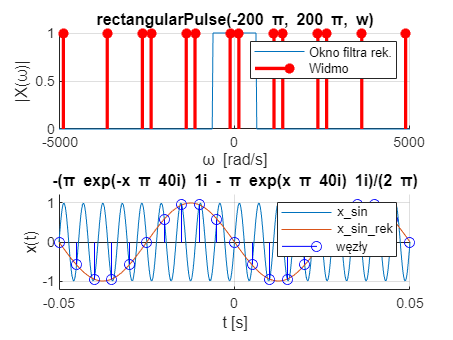

clear all; close all;
syms t x w K


fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;


s = 9/5; ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);


X_FT_sin = X_FT_sin_org + ... % oryginal widma
symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe


FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera


BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];


figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);
subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
stem(wezly, wezly_val, 'b');
legend('x\_sin','x\_sin\_rek', 'węzły');

Podpunkt g) s = 14/5

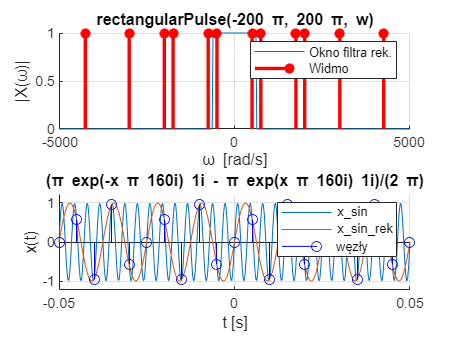

clear all; close all;
syms t x w K


fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;


s = 14/5; ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);


X_FT_sin = X_FT_sin_org + ... % oryginal widma
symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe


FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera


BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];


figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);
subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
stem(wezly, wezly_val, 'b');
legend('x\_sin','x\_sin\_rek', 'węzły');

Dla ułamków mniejszych od 1, sygnał był rekonstruowany poprawnie, zaś dla większych odbiegał od sygnału oryginalnego.

1.4 Zadanie 4

Dla s = 1/5

syms t x w K
fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 1/5;
ws = s*wg;


x_tr = ifourier(triangularPulse(-ws,ws,w));
x_FT_tr_org = triangularPulse(-ws,ws,w);


X_FT_tr = x_FT_tr_org + ... % oryginal widma
symsum((subs(x_FT_tr_org, w, w - K*wp ) + ...% 3 aliasy lewe
subs(x_FT_tr_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_tr_rek = ifourier(X_FT_tr*FILT_FT); % odwr. tarnsf. Fouriera

nodes = BND_t(1) : 1/fp : BND_t(2);
% uniknięcie zera w mianowniku
n = (length(nodes) - 1) / 2;
nodes1 = nodes(1 : n);
nodes2 = nodes(n + 2 : 2 * n + 1);
nodes_values = [subs(x_tr_rek, x, nodes1), ...
limit(x_tr_rek, x, 0), subs(x_tr_rek, x, nodes2)];


BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_tr,BND_w)
v_num = abs(double(subs(X_FT_tr, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');


subplot(2,1,2); hold on; grid on;
ezplot(x_tr, BND_t); % syg. próbkowany
ezplot(x_tr_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
stem(nodes, nodes_values, 'b');

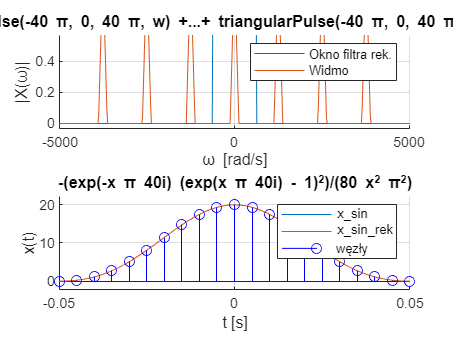

legend('x\_sin','x\_sin\_rek', 'węzły');

Dla s = 6/5

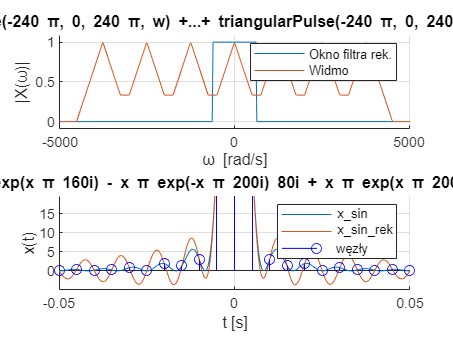

syms t x w K
fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 6/5;
ws = s*wg;


x_tr = ifourier(triangularPulse(-ws,ws,w));
x_FT_tr_org = triangularPulse(-ws,ws,w);


X_FT_tr = x_FT_tr_org + ... % oryginal widma
symsum((subs(x_FT_tr_org, w, w - K*wp ) + ...% 3 aliasy lewe
subs(x_FT_tr_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_tr_rek = ifourier(X_FT_tr*FILT_FT); % odwr. tarnsf. Fouriera

nodes = BND_t(1) : 1/fp : BND_t(2);
% uniknięcie zera w mianowniku
n = (length(nodes) - 1) / 2;
nodes1 = nodes(1 : n);
nodes2 = nodes(n + 2 : 2 * n + 1);
nodes_values = [subs(x_tr_rek, x, nodes1), ...
limit(x_tr_rek, x, 0), subs(x_tr_rek, x, nodes2)];


BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_tr,BND_w)
v_num = abs(double(subs(X_FT_tr, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');


subplot(2,1,2); hold on; grid on;
ezplot(x_tr, BND_t); % syg. próbkowany
ezplot(x_tr_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
stem(nodes, nodes_values, 'b');
legend('x\_sin','x\_sin\_rek', 'węzły');

Dla s = 11/5

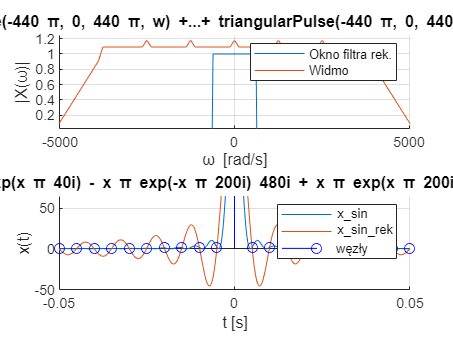

syms t x w K
fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 11/5;
ws = s*wg;


x_tr = ifourier(triangularPulse(-ws,ws,w));
x_FT_tr_org = triangularPulse(-ws,ws,w);


X_FT_tr = x_FT_tr_org + ... % oryginal widma
symsum((subs(x_FT_tr_org, w, w - K*wp ) + ...% 3 aliasy lewe
subs(x_FT_tr_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_tr_rek = ifourier(X_FT_tr*FILT_FT); % odwr. tarnsf. Fouriera

nodes = BND_t(1) : 1/fp : BND_t(2);
% uniknięcie zera w mianowniku
n = (length(nodes) - 1) / 2;
nodes1 = nodes(1 : n);
nodes2 = nodes(n + 2 : 2 * n + 1);
nodes_values = [subs(x_tr_rek, x, nodes1), ...
limit(x_tr_rek, x, 0), subs(x_tr_rek, x, nodes2)];


BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_tr,BND_w)
v_num = abs(double(subs(X_FT_tr, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');


subplot(2,1,2); hold on; grid on;
ezplot(x_tr, BND_t); % syg. próbkowany
ezplot(x_tr_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
stem(nodes, nodes_values, 'b');
legend('x\_sin','x\_sin\_rek', 'węzły');

Dla s = 16/5

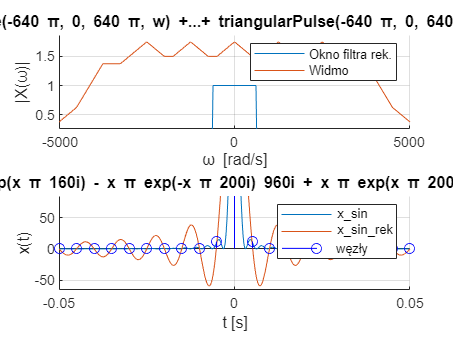

syms t x w K
fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 16/5;
ws = s*wg;


x_tr = ifourier(triangularPulse(-ws,ws,w));
x_FT_tr_org = triangularPulse(-ws,ws,w);


X_FT_tr = x_FT_tr_org + ... % oryginal widma
symsum((subs(x_FT_tr_org, w, w - K*wp ) + ...% 3 aliasy lewe
subs(x_FT_tr_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_tr_rek = ifourier(X_FT_tr*FILT_FT); % odwr. tarnsf. Fouriera

nodes = BND_t(1) : 1/fp : BND_t(2);
% uniknięcie zera w mianowniku
n = (length(nodes) - 1) / 2;
nodes1 = nodes(1 : n);
nodes2 = nodes(n + 2 : 2 * n + 1);
nodes_values = [subs(x_tr_rek, x, nodes1), ...
limit(x_tr_rek, x, 0), subs(x_tr_rek, x, nodes2)];


BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_tr,BND_w)
v_num = abs(double(subs(X_FT_tr, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');


subplot(2,1,2); hold on; grid on;
ezplot(x_tr, BND_t); % syg. próbkowany
ezplot(x_tr_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
stem(nodes, nodes_values, 'b');
legend('x\_sin','x\_sin\_rek', 'węzły');

Dla s = 4/5

syms t x w K
fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 4/5;
ws = s*wg;


x_tr = ifourier(triangularPulse(-ws,ws,w));
x_FT_tr_org = triangularPulse(-ws,ws,w);


X_FT_tr = x_FT_tr_org + ... % oryginal widma
symsum((subs(x_FT_tr_org, w, w - K*wp ) + ...% 3 aliasy lewe
subs(x_FT_tr_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_tr_rek = ifourier(X_FT_tr*FILT_FT); % odwr. tarnsf. Fouriera

nodes = BND_t(1) : 1/fp : BND_t(2);
% uniknięcie zera w mianowniku
n = (length(nodes) - 1) / 2;
nodes1 = nodes(1 : n);
nodes2 = nodes(n + 2 : 2 * n + 1);
nodes_values = [subs(x_tr_rek, x, nodes1), ...
limit(x_tr_rek, x, 0), subs(x_tr_rek, x, nodes2)];


BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_tr,BND_w)
v_num = abs(double(subs(X_FT_tr, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');


subplot(2,1,2); hold on; grid on;
ezplot(x_tr, BND_t); % syg. próbkowany
ezplot(x_tr_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
stem(nodes, nodes_values, 'b');

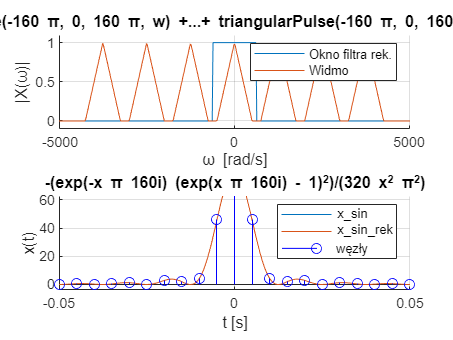

legend('x\_sin','x\_sin\_rek', 'węzły');

Dla s = 9/5

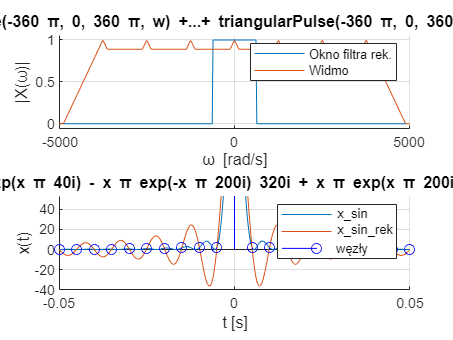

syms t x w K
fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 9/5;
ws = s*wg;


x_tr = ifourier(triangularPulse(-ws,ws,w));
x_FT_tr_org = triangularPulse(-ws,ws,w);


X_FT_tr = x_FT_tr_org + ... % oryginal widma
symsum((subs(x_FT_tr_org, w, w - K*wp ) + ...% 3 aliasy lewe
subs(x_FT_tr_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_tr_rek = ifourier(X_FT_tr*FILT_FT); % odwr. tarnsf. Fouriera

nodes = BND_t(1) : 1/fp : BND_t(2);
% uniknięcie zera w mianowniku
n = (length(nodes) - 1) / 2;
nodes1 = nodes(1 : n);
nodes2 = nodes(n + 2 : 2 * n + 1);
nodes_values = [subs(x_tr_rek, x, nodes1), ...
limit(x_tr_rek, x, 0), subs(x_tr_rek, x, nodes2)];


BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_tr,BND_w)
v_num = abs(double(subs(X_FT_tr, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');


subplot(2,1,2); hold on; grid on;
ezplot(x_tr, BND_t); % syg. próbkowany
ezplot(x_tr_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
stem(nodes, nodes_values, 'b');
legend('x\_sin','x\_sin\_rek', 'węzły');

Dla s = 14/5

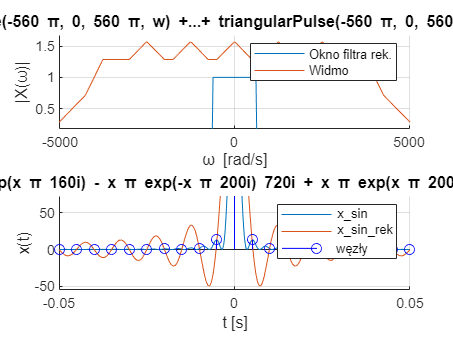

syms t x w K
fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 14/5;
ws = s*wg;


x_tr = ifourier(triangularPulse(-ws,ws,w));
x_FT_tr_org = triangularPulse(-ws,ws,w);


X_FT_tr = x_FT_tr_org + ... % oryginal widma
symsum((subs(x_FT_tr_org, w, w - K*wp ) + ...% 3 aliasy lewe
subs(x_FT_tr_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_tr_rek = ifourier(X_FT_tr*FILT_FT); % odwr. tarnsf. Fouriera

nodes = BND_t(1) : 1/fp : BND_t(2);
% uniknięcie zera w mianowniku
n = (length(nodes) - 1) / 2;
nodes1 = nodes(1 : n);
nodes2 = nodes(n + 2 : 2 * n + 1);
nodes_values = [subs(x_tr_rek, x, nodes1), ...
limit(x_tr_rek, x, 0), subs(x_tr_rek, x, nodes2)];


BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_tr,BND_w)
v_num = abs(double(subs(X_FT_tr, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');


subplot(2,1,2); hold on; grid on;
ezplot(x_tr, BND_t); % syg. próbkowany
ezplot(x_tr_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
stem(nodes, nodes_values, 'b');
legend('x\_sin','x\_sin\_rek', 'węzły');

1.5 Zadanie 5

Dla s = 1/5

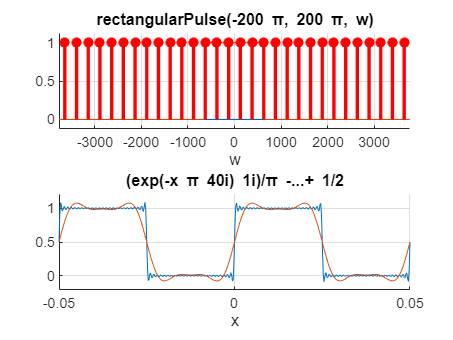

syms t x w K
s = 1/5;
fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
ws = s*wg;
fs = s*fg;
T = 1/fs;


x = rectangularPulse(0,T/2,t);
NT = 50;
sumX = 0;
ind = -NT:NT;
BND = [-T/2 T/2];
for n=ind
    Xn = 1/T*int(x*exp(-1i*ws*n*t),t,BND);
    sumX = sumX +Xn * dirac(w-n*ws);
end

X_FT_oryg = 2*pi*sumX;
FILT_FT = rectangularPulse(-wg,wg,w);
x_tr_rek = ifourier(X_FT_oryg*FILT_FT);
BND_t = [-10/fp;10/fp];
t_SMP = [BND_t(1):1/(10*fp):BND_t(2);];
BND_w = [-3*wp;3*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2);];

figure;

subplot(2,1,1); hold on; grid on;
ezplot(X_FT_oryg,BND_w);
ezplot(FILT_FT, BND_w);
v_num = subs(imag(X_FT_oryg),w,w_SMP);
n = find(abs(v_num) == inf);
stem(w_SMP(n),abs(sign(v_num(n))),'r*', 'LineWidth', 2);

w_num = subs(real(X_FT_oryg),w,w_SMP);
n = find(abs(v_num) == inf);
stem(w_SMP(n),abs(sign(v_num(n))),'r*', 'LineWidth', 2)
subplot(2,1,2); hold on; grid on;
ezplot(ifourier(X_FT_oryg),BND_t);
ezplot(x_tr_rek, BND_t);

Dla s = 4/5

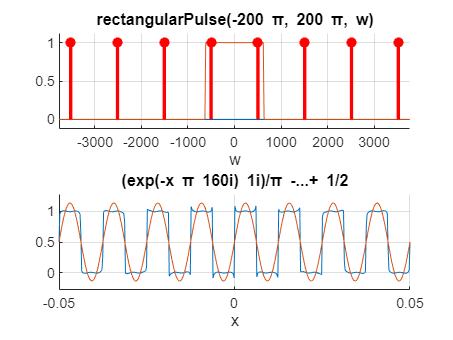

syms t x w K
s = 4/5;
fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
ws = s*wg;
fs = s*fg;
T = 1/fs;


x = rectangularPulse(0,T/2,t);
NT = 50;
sumX = 0;
ind = -NT:NT;
BND = [-T/2 T/2];
for n=ind
    Xn = 1/T*int(x*exp(-1i*ws*n*t),t,BND);
    sumX = sumX +Xn * dirac(w-n*ws);
end

X_FT_oryg = 2*pi*sumX;
FILT_FT = rectangularPulse(-wg,wg,w);
x_tr_rek = ifourier(X_FT_oryg*FILT_FT);
BND_t = [-10/fp;10/fp];
t_SMP = [BND_t(1):1/(10*fp):BND_t(2);];
BND_w = [-3*wp;3*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2);];

figure;

subplot(2,1,1); hold on; grid on;
ezplot(X_FT_oryg,BND_w);
ezplot(FILT_FT, BND_w);
v_num = subs(imag(X_FT_oryg),w,w_SMP);
n = find(abs(v_num) == inf);
stem(w_SMP(n),abs(sign(v_num(n))),'r*', 'LineWidth', 2);

w_num = subs(real(X_FT_oryg),w,w_SMP);
n = find(abs(v_num) == inf);
stem(w_SMP(n),abs(sign(v_num(n))),'r*', 'LineWidth', 2)
subplot(2,1,2); hold on; grid on;
ezplot(ifourier(X_FT_oryg),BND_t);
ezplot(x_tr_rek, BND_t);

Dla s = 1

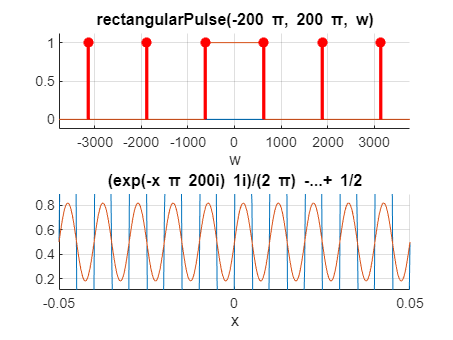

syms t x w K
s = 1;
fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
ws = s*wg;
fs = s*fg;
T = 1/fs;


x = rectangularPulse(0,T/2,t);
NT = 50;
sumX = 0;
ind = -NT:NT;
BND = [-T/2 T/2];
for n=ind
    Xn = 1/T*int(x*exp(-1i*ws*n*t),t,BND);
    sumX = sumX +Xn * dirac(w-n*ws);
end

X_FT_oryg = 2*pi*sumX;
FILT_FT = rectangularPulse(-wg,wg,w);
x_tr_rek = ifourier(X_FT_oryg*FILT_FT);
BND_t = [-10/fp;10/fp];
t_SMP = [BND_t(1):1/(10*fp):BND_t(2);];
BND_w = [-3*wp;3*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2);];

figure;

subplot(2,1,1); hold on; grid on;
ezplot(X_FT_oryg,BND_w);
ezplot(FILT_FT, BND_w);
v_num = subs(imag(X_FT_oryg),w,w_SMP);
n = find(abs(v_num) == inf);
stem(w_SMP(n),abs(sign(v_num(n))),'r*', 'LineWidth', 2);

w_num = subs(real(X_FT_oryg),w,w_SMP);
n = find(abs(v_num) == inf);
stem(w_SMP(n),abs(sign(v_num(n))),'r*', 'LineWidth', 2)
subplot(2,1,2); hold on; grid on;
ezplot(ifourier(X_FT_oryg),BND_t);
ezplot(x_tr_rek, BND_t);

Dla s = 6/5

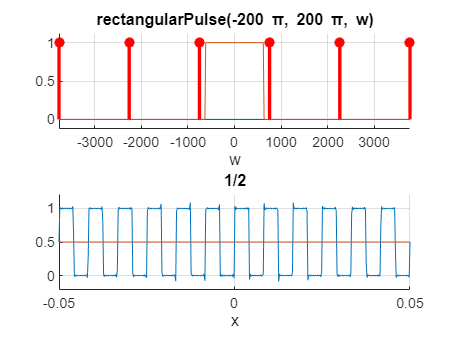

syms t x w K
s = 6/5;
fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
ws = s*wg;
fs = s*fg;
T = 1/fs;


x = rectangularPulse(0,T/2,t);
NT = 50;
sumX = 0;
ind = -NT:NT;
BND = [-T/2 T/2];
for n=ind
    Xn = 1/T*int(x*exp(-1i*ws*n*t),t,BND);
    sumX = sumX +Xn * dirac(w-n*ws);
end

X_FT_oryg = 2*pi*sumX;
FILT_FT = rectangularPulse(-wg,wg,w);
x_tr_rek = ifourier(X_FT_oryg*FILT_FT);
BND_t = [-10/fp;10/fp];
t_SMP = [BND_t(1):1/(10*fp):BND_t(2);];
BND_w = [-3*wp;3*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2);];

figure;

subplot(2,1,1); hold on; grid on;
ezplot(X_FT_oryg,BND_w);
ezplot(FILT_FT, BND_w);
v_num = subs(imag(X_FT_oryg),w,w_SMP);
n = find(abs(v_num) == inf);
stem(w_SMP(n),abs(sign(v_num(n))),'r*', 'LineWidth', 2);

w_num = subs(real(X_FT_oryg),w,w_SMP);
n = find(abs(v_num) == inf);
stem(w_SMP(n),abs(sign(v_num(n))),'r*', 'LineWidth', 2)
subplot(2,1,2); hold on; grid on;
ezplot(ifourier(X_FT_oryg),BND_t);
ezplot(x_tr_rek, BND_t);